close all

%Time Conditions
time_step = 1;
time_end = 100;

% fuel = 2723900;
%Variables
mass_empty = 185300;
mass_full = 2909200;
mass_burn = 3930.6;
mass_burn_complete = 0;
gravity_c = 3.721;
uni_grav_coeff = 6.674e-11;
% 3.721
power_level = 1;
exhaust_velocity = 2.58e4 * power_level;
rocket_drag_coeff = 1.5;
rocket_crossection = 31.4;

% Arrays
t = 1:time_step:time_end;

%MARS
M_mass = 6.39e23;
M_radius = 3389500;
M_atmos = 0.02; %kg/m3
M_atm_density = zeros(1,length(t));
atmospheric_37_percent = 10800;


%%ACCELERATION
%x, y and z
a_x = zeros(1,length(t));
a_y = zeros(1,length(t));
a_x(1) = 0;
a_y(1) = 0;
%angular x rocket
a_ang_r_x = zeros(1,length(t));
a_ang_r_x(1) = 0;
%angular x RESULTING
a_ang_res_x = zeros(1,length(t));
a_ang_res_x(1) = 0;


%%VELOCITY
%x, y and z
v_x = zeros(1,length(t));
v_y = zeros(1,length(t));
v_y(1) = 0;
v_x(1) = 0;

%angular x rocket
v_ang_r_x = zeros(1,length(t));
v_ang_r_x(1) = 0;
%angular x RESULTING
v_ang_res_x = zeros(1,length(t));
v_ang_res_x(1) = 0;

%%POSITION
%x, y and z
p_x = zeros(1,length(t));
p_y = zeros(1,length(t));
p_x(1) = 0;
p_y(1) = 1;
%angular x
%p_ang_e_x = zeros(1,length(t));
p_ang_e_x = 30;
%angular x rocket
p_ang_r_x = zeros(1,length(t));
p_ang_r_x(1) = 30;
%angular x RESULTING
%p_ang_res_x = zeros(1,length(t));
p_ang_res_x = 30;


%angle = zeros(1,length(t));
%Rocket engine points straight down
angle = 50;

mass_change = zeros(1,length(t));

mass_change(1) = mass_full;

for i = 2:length(t)
    
    
    %%DEFINE BURN TIME
    if i >= 10
        dmdt = mass_burn_complete;
        %FUEL CHECK
    elseif mass_change(i-1)> mass_empty
        dmdt = mass_burn;
    else
        dmdt = mass_burn_complete;
    end
    
    %%y(i) luftmotstånd - i höjd - M_atmos 0.02
    M_atm_density(1+round(p_y(i))) = M_atmos - M_atmos*0.37/(atmospheric_37_percent);
    M_atmos = M_atm_density(1+round(p_y(i))) - 0.00127/atmospheric_37_percent;
    
    mass_change(i) = mass_change(i-1) - time_step*dmdt;
    
    a_y(i) = (exhaust_velocity * cosd(angle)/mass_change(i))*dmdt - uni_grav_coeff*(M_mass/((M_radius + p_y(i-1))^2)) - (1/2)*rocket_crossection*rocket_drag_coeff*abs(v_y(i-1)*v_y(i-1))*M_atm_density(1+round(p_y(i)))/mass_change(i);
    a_x(i) = (exhaust_velocity * sind(angle)/mass_change(i))*dmdt - (1/2)*rocket_crossection*rocket_drag_coeff*abs(v_x(i-1)*v_x(i-1))*M_atm_density(1+round(p_y(i)))/mass_change(i);
    
    %a_ang_res_x(i) = (exhaust_velocity * sind(p_ang_r_x(i)+p_ang_e_x)*40)/2*360;
    
    v_y(i) = eulerfunc(v_y(i-1),time_step,a_y(i));
    v_x(i) = eulerfunc(v_x(i-1),time_step,a_x(i));
    
    
    %v_ang_res_x(i) = eulerfunc(a_ang_res_x(i-1),time_step,a_ang_res_x(i));
    
    p_y(i) = eulerfunc(p_y(i-1),time_step,v_y(i));
    p_x(i) = eulerfunc(p_x(i-1),time_step,v_x(i));
    
    %p_ang_res_x(i) = eulerfunc(v_ang_res_x(i-1),time_step,v_ang_res_x(i));
    
    %     angle(i) = atand(v_y(i)/v_x(i))
    
    %%COLLISION CHECK
    if p_y(i) < 0
        a_y(i) = 0;
        a_x(i) = 0;
        v_y(i) = 0;
        v_x(i) = 0;
        
        fprintf('You crashed the spaceship. Everyone has died. \nYour efforts as a pilot will be remembered in every textbook of the future as a total disaster. \nWhat remains of you are buried in a shallow unmarked grave.\nThe soviet union will continue its testing. You will not.');
        break
    end
    
end

You crashed the spaceship. Everyone has died. 
Your efforts as a pilot will be remembered in every textbook of the future as a total disaster. 
What remains of you are buried in a shallow unmarked grave.
The soviet union will continue its testing. You will not.


plot(t,a_y,"Color","r")
ylabel("Acceleration m/s^2")
xlabel("Time t")
hold on
plot(t,a_x,"Color","b")
legend("Acceleration Y","Acceleration X")
hold off
% saveas(gcf,'alt/time.png')

figure
plot(t,v_y,"Color","r")
ylabel("Velocity m/s")
xlabel("Time t")
hold on
plot(t,v_x,"Color","b")
legend("Velocity Y","Velocity X")
hold off
% saveas(gcf,'vel/time.png')

figure
plot(t,p_y,"Color","r")
ylabel("Altitude")
xlabel("Time t")
hold on
plot(t,p_x,"Color","b")
legend("Position Y","Position X")
hold off
% saveas(gcf,'acc/time.png')

figure
ax=axes;
set(ax,'xlim',[0 20000],'ylim',[0 20000]);
hold (ax)

Current plot held


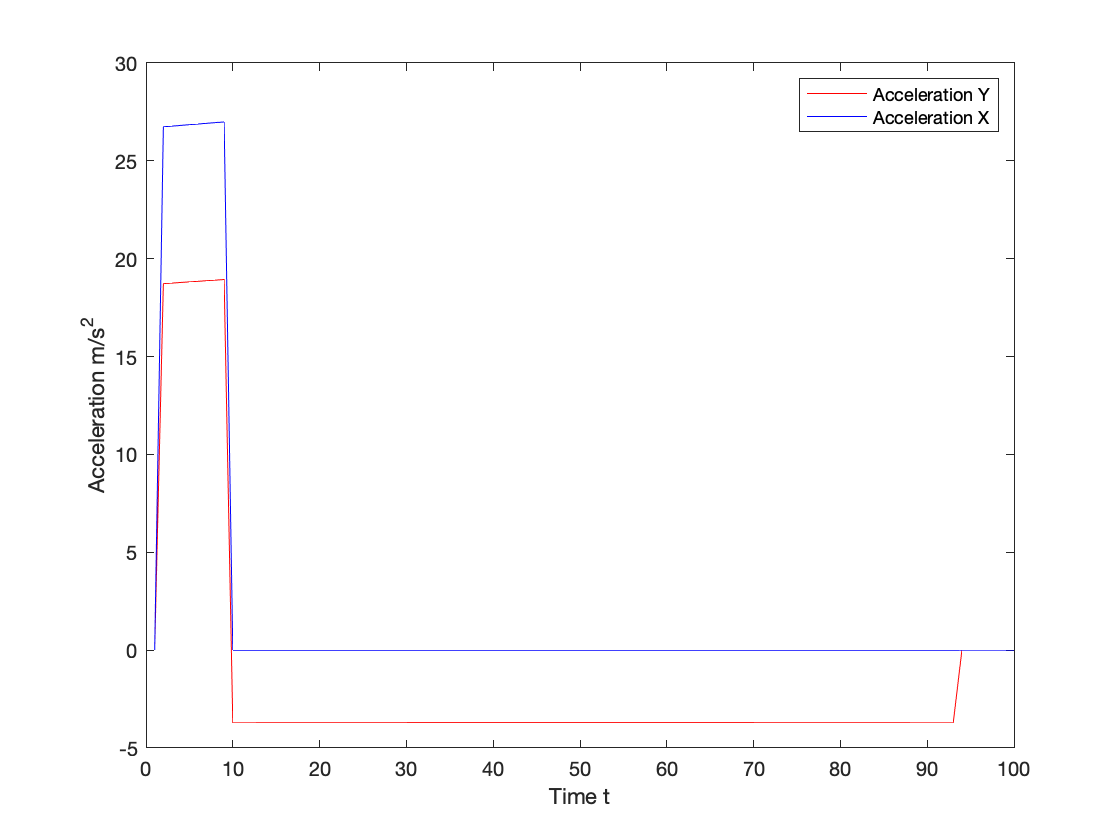

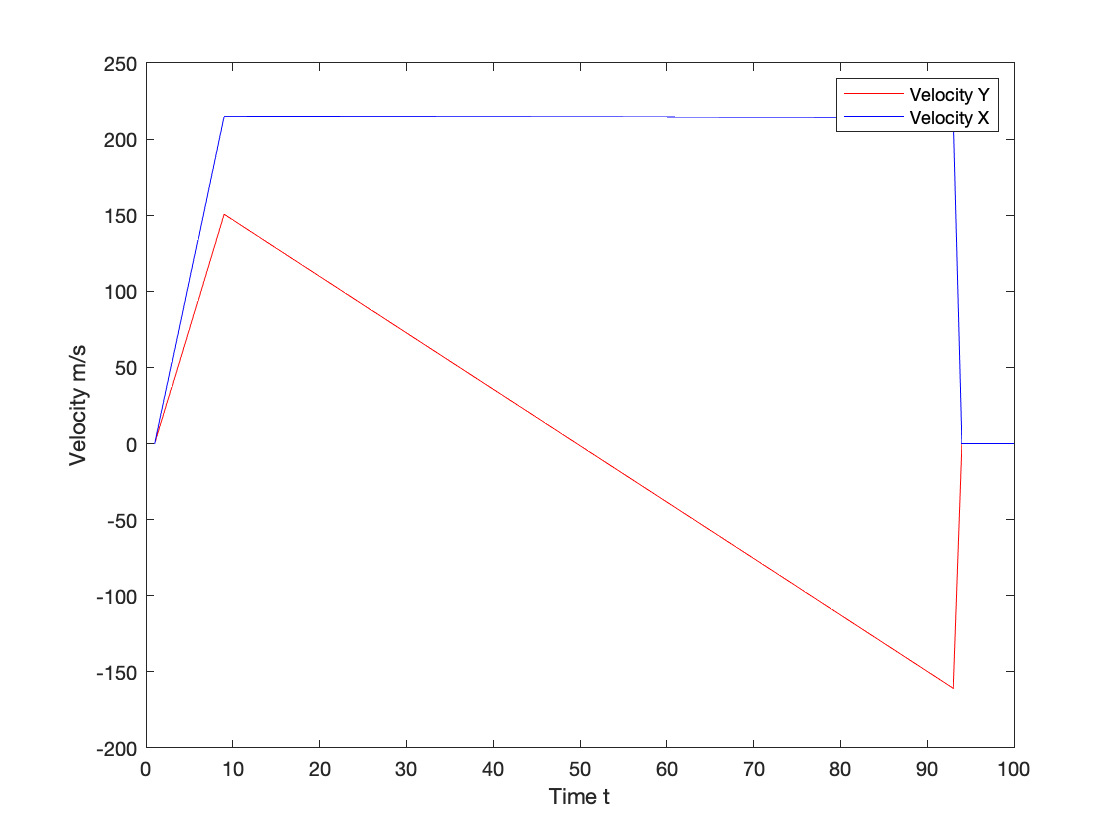

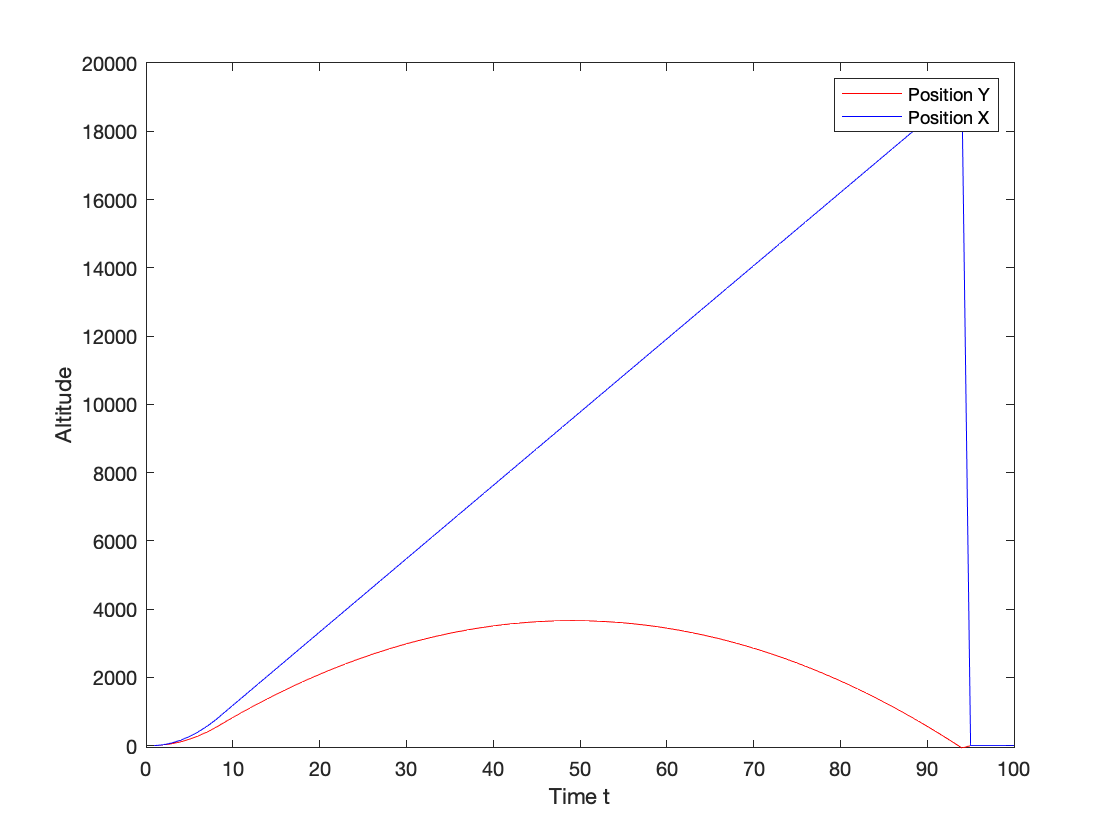

comet(ax,p_x,p_y)

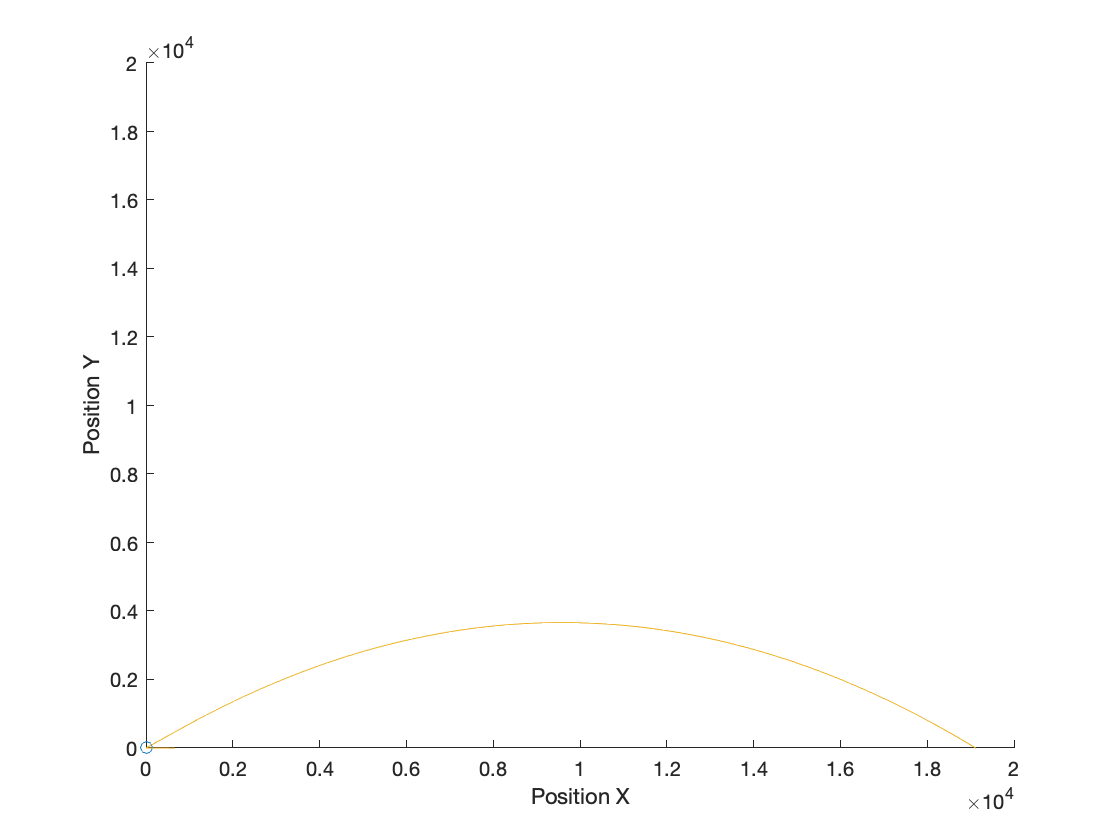

ylabel("Position Y")
xlabel("Position X")

% saveas(gcf,'pos/time.png')
